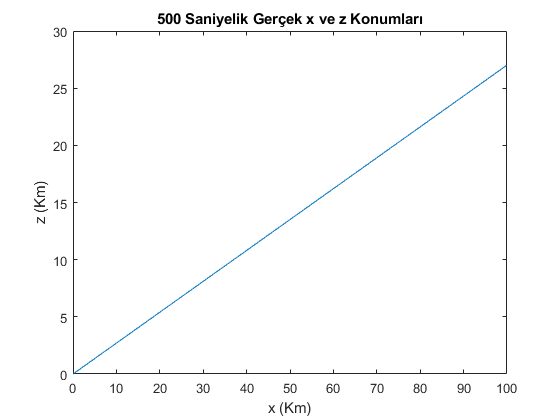

n=12;
v=195+n; %m/s
y0= 6355000; %m yükseklik-sabit
x0=0;
z0=0;
t_delta=1;
gama=(15+n/100)*pi/180;
adim=500;
x=x0:v*t_delta*cos(gama):v*t_delta*cos(gama)*adim;
z=z0:v*t_delta*sin(gama):v*t_delta*sin(gama)*adim;
y=zeros(1,adim+1)+3000;

figure(1)
h1=plot(x/1000,z/1000);
title('500 Saniyelik Gerçek x ve z Konumları');
xlabel('x (Km)');
ylabel('z (Km)');

50 saniye sonunda 103500 metre yol katedilmiştir.

m1=(z(100)-z(99))/(x(100)-x(99));
m2=-1/m1;

st1=[50000 , 13500  , 500];
st2=[ 172200  , 136200 , 1000];
st3=[  95190  ,-153700 , 1500];
st4=[0 0 0];


%Her bir istasyon ile uçak arasında olan mesafe
D1=sqrt( (st1(1)-x).^2 + (st1(2)-z).^2 + (st1(3)-y).^2 );
D2=sqrt( (st2(1)-x).^2 + (st2(2)-z).^2 + (st2(3)-y).^2 );
D3=sqrt( (st3(1)-x).^2 + (st3(2)-z).^2 + (st3(3)-y).^2 );
D4=sqrt( (st4(1)-x).^2 + (st4(2)-z).^2 + (st4(3)-y).^2 );

%Her bir istasyonun 0,0,0 noktasına olan mesafesi
l1 = sqrt(st1(1)^2 + st1(2)^2 + st1(3)^2 );
l2 = sqrt(st2(1)^2 + st2(2)^2 + st2(3)^2 );
l3 = sqrt(st3(1)^2 + st3(2)^2 + st3(3)^2 );
l4 = sqrt(st4(1)^2 + st4(2)^2 + st4(3)^2 );


%c1 = [St1(1)-St2(1), St1(2)-St2(2), St1(3)-St2(3)]
%c2 = [St1(1)-St3(1), St1(2)-St3(2), St1(3)-St3(3)]
%c3 = [St2(1)-St3(1), St2(2)-St3(2), St2(3)-St3(3)]

c1=0.5* (D2.^2 - D1.^2 + l1^2 - l2^2);
c2=0.5* (D3.^2 - D1.^2 + l1^2 - l3^2);
c3=0.5* (D3.^2 - D2.^2 + l2^2 - l3^2);



err

sigma_D=10; %metre
bias=10+n; % bias
% D Uçağa kadar olan mesafe
% Delta_D = Uçaktan iki çeşitli antene kadar olan mesafeler farkı
% Uçaktan iki çeşitli antene kadar olan mesafeler toplamı
% Belirli antene göre açıların doğrultman kosinüsleri
% Uçağın alfa:azimut ve beta: konum açılarını
% Kayıt olan parametrelerin değişme hızleri

DZ1 = D1 + bias + sigma_D*randn(1,501);
DZ2 = D2 + bias + sigma_D*randn(1,501);
DZ3 = D3 + bias + sigma_D*randn(1,501);
DZ4 = D4 + bias + sigma_D*randn(1,501);

e1=( c1.*(st2(2)-st3(2)) - c3.*(st1(2)-st2(2)) ) / ( (st1(1)-st2(1)).*(st2(2) -st3(2)) - (st2(1)-st3(1)).*( st1(2)-st2(2))   );

e2=( c1.*(st1(1)-st3(1)) - c2.*(st1(1)-st2(1)) ) / ( (st1(1)-st3(1)).*(st1(2) -st2(2)) - (st1(1)-st2(1)).*( st1(2)-st3(2))   );

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


a= ( (st1(3)-st2(3))*(st2(2)-st3(2)) - (st2(3)-st3(3))*(st1(2)-st2(2)) ) / ( (st1(1)-st2(1))*(st2(2)-st3(2)) - (st2(1)-st3(1))*(st1(2)-st2(2)) );

b= ( (st1(3)-st2(3))*(st1(1)-st3(1)) - (st1(3)-st3(3))*(st1(1)-st2(1)) ) / ( (st1(1)-st3(1))*(st1(2)-st2(2)) - (st1(1)-st2(1))*(st1(2)-st3(2)) );

p_y2=ones(1,501)*(a^2 + b^2 + 1) ;
p_y=2*( st1(1)*a - st1(3) + st1(2)*b - a.*e1 - b.*e2) ;
p_c= -1*(D1(1)^2 - l1^2 - e1.^2 + 2*st1(1).*e1 - e2.^2 + 2*st1(2).*e2) ;  

polynom=[p_y2',p_y', p_c'];

% rts{1,501};
% figure(6)
% for i=1:501
%     rts{1,i}=roots((polynom(i,1).coeff));
%     plot(i,(rts{i,1}))
%     hold on
% end


y1= sqrt( DZ1.^2 - l1^2 - e1.^2 + 2*st1(1).*e1 + 2*st1(2).*e2 -e2.^2 );
disc=[polynom(:,2).^2-4*polynom(:,1).*polynom(:,3), polynom(:,2).^2 + 4*polynom(:,1).*polynom(:,3)]

disc = 	1.0e+10 *

    0.0032   -0.0032
    0.0118   -0.0118
    0.0203   -0.0203
    0.0288   -0.0288
    0.0373   -0.0372
    0.0457   -0.0457
    0.0541   -0.0540
    0.0624   -0.0624
    0.0707   -0.0707
    0.0790   -0.0790




x1=e1-a.*y1;
z1=e2-b.*y1;


figure(2)
plot(x1, z1, 'c+:')
hold on
plot(x,z, 'r.-')
title("y1=y2=y3=a=b=0")
xlabel("x(m)")
ylabel("z(m)")
legend('Hesaplanan Konum','Gerçek Konum');


figure(5)
plot(y);
hold on
plot(y1);
title("y1="+ st1(3)+ " y2="+st2(3) + " y3="+st3(3) + " a=" +a + " b="+b);
xlabel("zaman (sn)");
ylabel("y (m)");
legend("Gerçek Yükseklik", "Hesaplanan Yükseklik");

%[std(x-x1), std(z-z1), std(y-y1)]

2.Kısım: Mesafe Farkı. 4. istasyon (0,0,0) noktasına yerleştirilmiştir.

Mesafeler Toplamı için ilk 3 satırın düzenlenmesi yeterlidir.

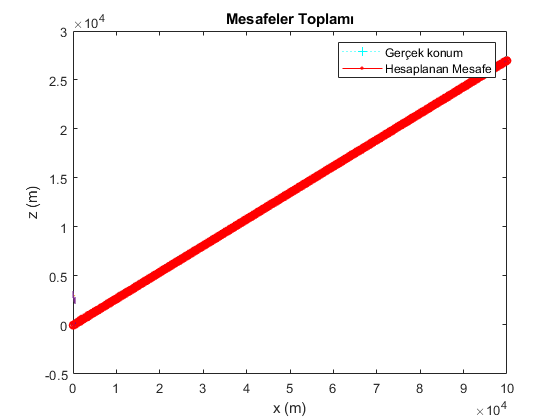

DD1 = DZ4 - DZ1;
DD2 = DZ4 - DZ2;
DD3 = DZ4 - DZ3;

%f1= st1(1).*x + st1(2).*y +  st1(3).*z - DD1;
%f2= st2(1).*x + st2(2).*y +  st2(3).*z - DD1;
%f3= st3(1).*x + st3(2).*y +  st3(3).*z - DD1;

f1=0.5 * (l1^2 - DD1.^2);
f2=0.5 * (l2^2 - DD2.^2);
f3=0.5 * (l3^2 - DD3.^2);

A = st1(1)* ( st3(2).*DD2 - st2(2).*DD3 ) - ...
    st1(2)* ( st3(1).*DD2 - st2(1).*DD3 ) - ...
    DD1.* (st2(1)*st3(2) - st3(1)*st2(2) ) ;

x2 = 1./A .*(f1.*(st3(2).*DD2 - st2(2).*DD3) -...
         st1(2).*(f3.*DD2 - f2.*DD3) - ...
         DD1.*(f2.*st3(2) - f3.*st2(2) ) );

z2 = 1./A .*(  st1(1).*(f3.*DD2 - f2.*DD3) -...
               f1    .*(st3(1).*DD2 - st2(1).*DD3) - ...
               DD1   .*(st2(1).*f3 - st3(1).*f2 ) ...
            );

D= 1./A .*(...
    st1(1).*( st2(2).*f3 - st3(2).*f2) -...
    st1(2).*( st2(1).*f3 - st3(1).*f2) - ...
    f1    .*( st2(1).*st3(2) - st3(1).*st2(2) ) ...
    );

y2=sqrt(D.^2 - x2.^2 - z2.^2);

figure(3)
plot(x,z, 'b.')
hold on
plot(x2,z2,'ro')
title("Mesafeler Toplamı")
xlabel("x (m)");
ylabel("z (m)");
legend("Gerçek konum", "Hesaplanan Mesafe")

hold off

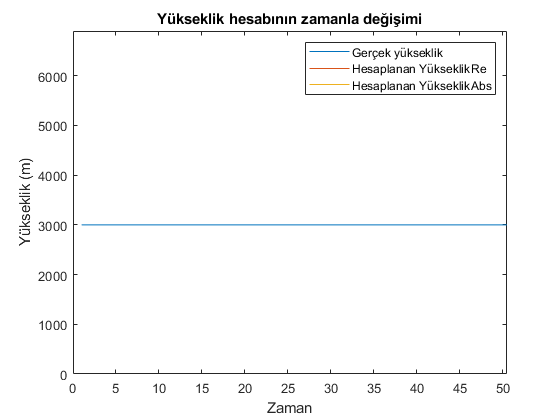


figure(4)

plot(y);
hold on
plot(real(y2));
hold on
plot(abs(y2));
title("Yükseklik hesabının zamanla değişimi");
xlabel("Zaman");
ylabel("Yükseklik (m)");
legend("Gerçek yükseklik","Hesaplanan Yükseklik{Re}", "Hesaplanan Yükseklik{Abs}");

xlim([0.0 47.6])
ylim([0 6527])

xlim([0.0 50.5])
ylim([0 6898])

mesafe=sqrt((z2(end)-z2(1))^2 + (x2(end)-x2(1))^2);
[std(x-x2), std(z-z2), std(y-y2)]

ans = 	1.0e+04 *

    0.0014    0.0009    2.7135


4. Kısım: 

DD1 = DZ4 + DZ1;
DD2 = DZ4 + DZ2;
DD3 = DZ4 + DZ3;

%f1= st1(1).*x + st1(2).*y +  st1(3).*z - DD1;
%f2= st2(1).*x + st2(2).*y +  st2(3).*z - DD1;
%f3= st3(1).*x + st3(2).*y +  st3(3).*z - DD1;

f1=0.5 * (l1^2 - DD1.^2);
f2=0.5 * (l2^2 - DD2.^2);
f3=0.5 * (l3^2 - DD3.^2);

A = st1(1)* ( st3(2).*DD2 - st2(2).*DD3 ) - ...
    st1(2)* ( st3(1).*DD2 - st2(1).*DD3 ) - ...
    DD1.* (st2(1)*st3(2) - st3(1)*st2(2) ) ;

x3 = 1./A .*(f1.*(st3(2).*DD2 - st2(2).*DD3) -...
         st1(2).*(f3.*DD2 - f2.*DD3) - ...
         DD1.*(f2.*st3(2) - f3.*st2(2) ) );

z3 = 1./A .*(  st1(1).*(f3.*DD2 - f2.*DD3) -...
               f1    .*(st3(1).*DD2 - st2(1).*DD3) - ...
               DD1   .*(st2(1).*f3 - st3(1).*f2 ) ...
            );

D= 1./A .*(...
    st1(1).*( st2(2).*f3 - st3(2).*f2) -...
    st1(2).*( st2(1).*f3 - st3(1).*f2) - ...
    f1    .*( st2(1).*st3(2) - st3(1).*st2(2) ) ...
    );

y3=sqrt(D.^2 - x2.^2 - z2.^2);

